### **Método De Gauss-Jacobi**


$$x^{k+1} =\Phi(x^{k})$$
 


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)} - \cdots - a_{1n}x_{n}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k)} - a_{23}x_{3}^{(k)} - \cdots - a_{2n}x_{n}^{(k)})\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k)} - a_{32}x_{2}^{(k)} - \cdots - a_{3n}x_{n}^{(k)})\\
  \vdots               = \vdots \\
  x_{n}^{(k+1)}=  \frac{1}{a_{nn}} ( b_{n} - a_{n1}x_{1}^{(k)} - a_{n2}x_{2}^{(k)} - \cdots - a_{n,n-1}x_{n-1}^{(k)})
$$


Vamos encontrar a solução aproximada do sistema 


$$\begin{cases}
10x_{1} + 2x_{2} + x_{3} = 7\\
x_{1} + 5x_{2} + x_{3} = -8\\
2x_{1} + 3x_{2} + 10x_{3} = 6
\end{cases}$$


com chute inicial $x^{0} = (0.7,-1.6,0.6)$ e $\epsilon=0.05$.

Graficamente, 

X = -2:0.01:5;
Y = -2:0.01:5;
z1 = 5 - 5*X - Y;
z2 = 6 - 3*X - 4*Y;
z3 = 0 - (2/6)*X - (3/6)*Y;
plot3(X,Y,z1,'b')

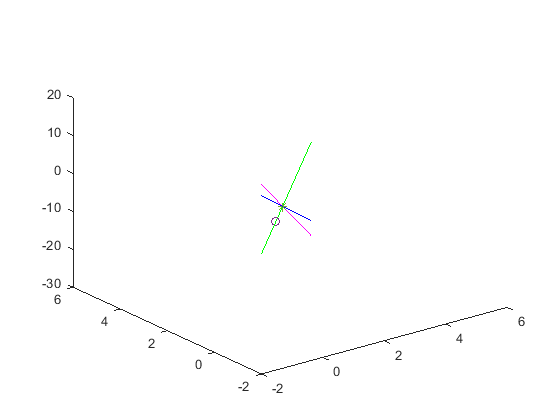

hold on
plot3(X,Y,z2,'m')
plot3(X,Y,z3, 'g')
plot3(0,0,0, 'o')
plot3(0.9574,0.9618,-0.8273,'*')
hold off

**Implementação Gauss-Jacobi por componente:**


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k)} - a_{23}x_{3}^{(k)} )\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k)} - a_{32}x_{2}^{(k)})


$$


A = [10 2  1;
      1 5  1;
      2 3 10];


b = [7;-8;6];
x0 = [0.7;-1.6;0.6];

x1 = (1/A(1,1)) * (b(1) - A(1,2) * x0(2) - A(1,3) * x0(3));
x2 = (1/A(2,2)) * (b(2) - A(2,1) * x0(1) - A(2,3) * x0(3));
x3 = (1/A(3,3)) * (b(3) - A(3,1) * x0(1) - A(3,2) * x0(2));

x_1 = [x1; x2; x3];
d0 = norm(x_1-x0, inf)

d0 = 0.3400

x0 = x_1;

x1 = (1/A(1,1)) * (b(1) - A(1,2) * x0(2) - A(1,3) * x0(3));
x2 = (1/A(2,2)) * (b(2) - A(2,1) * x0(1) - A(2,3) * x0(3));
x3 = (1/A(3,3)) * (b(3) - A(3,1) * x0(1) - A(3,2) * x0(2));

x_2 = [x1; x2; x3];
d0 = norm(x_2-x0, inf)

d0 = 0.1200

A = [10 2 1;1 5 1;2 3 10];
b = [7;-8;6];
x0 = [0.7;-1.6;0.6];
tol = 0.05;
k=0;
d=10;
while(d > tol)
    x1 = (1/A(1,1)) * (b(1) - A(1,2) * x0(2) - A(1,3) * x0(3));
    x2 = (1/A(2,2)) * (b(2) - A(2,1) * x0(1) - A(2,3) * x0(3));
    x3 = (1/A(3,3)) * (b(3) - A(3,1) * x0(1) - A(3,2) * x0(2));

    x = [x1; x2; x3];
    d = norm(x-x0, inf);
    x0 = x;
    k=k+1;
end
x, d

x =     0.9994
   -1.9888
    0.9984


d = 0.0324

**Implementação Gauss-Jacobi matricial**


$$x^{k+1} =Cx^{k} + g$$


A = [10 2 1;1 5 1;2 3 10];
b = [7;-8;6];
x0 = zeros(3,1);
n = length(x0);

for i = 1:n
    for j = 1:n
        if i == j
            C(i,j) = 0;
        else
            C(i,j) = -A(i,j)/A(i,i);
        end
    end
    g(i) = b(i)/A(i,i);
end
C, g

C =          0   -0.2000   -0.1000
   -0.2000         0   -0.2000
   -0.2000   -0.3000         0


g =     0.7000   -1.6000    0.6000


% utilizando o método
k = 0;
x0 = [0.7;-1.6;0.6];
tol = 0.05;
d = 20;
while(d > tol)
    x = C*x0 + g';
    d = norm(x-x0, inf);
    x0 = x;
    k = k+1;
    xit(k,:) = x0;
    dit(k,:) = d;
end
xit, dit

xit =     0.9600   -1.8600    0.9400
    0.9780   -1.9800    0.9660
    0.9994   -1.9888    0.9984


dit =     0.3400
    0.1200
    0.0324


**Critério de Linhas** para análise de convergência do método de Gaus-Jacobi (matriz de ordem 3)


$$\alpha_{1} = \frac{|a_{12}|+|a_{13}|}{|a_{11}|}\\
\alpha_{2} = \frac{|a_{21}|+|a_{23}|}{|a_{22}|}\\
\alpha_{3} = \frac{|a_{31}|+|a_{32}|}{|a_{33}|}\\

\alpha = \max_{ 1 \leq i \leq 3}|\alpha_{1},\alpha_{2},\alpha_{3}|<1$$


%Implementação do critério de linhas
A = [5 1 1;3 4 1;2 3 6];

### **Método De Gauss-Seidel**


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)} - \cdots - a_{1n}x_{n}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k+1)} - a_{23}x_{3}^{(k)} - \cdots - a_{2n}x_{n}^{(k)})\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k+1)} - a_{32}x_{2}^{(k+1)} - \cdots - a_{3n}x_{n}^{(k)})\\
  \vdots               = \vdots \\
  x_{n}^{(k+1)}=  \frac{1}{a_{nn}} ( b_{n} - a_{n1}x_{1}^{(k+1)} - a_{n2}x_{2}^{(k+1)} - \cdots - a_{n,n-1}x_{n-1}^{(k+1)})
$$


Vamos encontrar a solução aproximada do sistema 


$$\begin{cases}
5x_{1} + x_{2} + x_{3} = 5\\
3x_{1} + 4x_{2} + x_{3} = 6\\
2x_{1} + 3x_{2} + 6x_{3} = 0
\end{cases}$$


com chute inicial $x^{0} = (0,0,0)$ e $\epsilon=0.05$.

A = [5 1 1;3 4 1;2 3 6];
b = [5;6;0];
x0 = [0;0;0];

Critério de Sassenfeld para análise de convergência do método de Gaus-Seidel (matriz de ordem 3)


$$\beta_{1} = \frac{|a_{12}|+|a_{13}|}{|a_{11}|}\\
\beta_{2} = \frac{|a_{21}|\beta_{1}+|a_{23}|}{|a_{22}|}\\
\alpha_{3} = \frac{|a_{31}|\beta_{1}+|a_{32}|\beta_{2}}{|a_{33}|}\\

\beta = \max_{ 1 \leq i \leq 3}|\beta_{1},\beta_{2},\beta_{3}|<1$$


%Implementação do critério de Sassenfeld
A = [5 1 1;3 4 1;2 3 6];

alpha1 = (abs(A(1,2))+abs(A(1,3))) / abs(A(1,1));
alpha2 = (abs(A(2,1))+abs(A(2,3))) / abs(A(2,2));
alpha3 = (abs(A(3,1))+abs(A(3,2))) / abs(A(3,3));

alpha = max([alpha1, alpha2, alpha3])

alpha = 1

A = [5 1 1;3 4 1;2 3 6];
[m n] = size(A);
for k = 1:n
    s = 0;
    for j = 1:n
        if j ~= k 
            s = s + abs(A(k,j));
        end
    end
    alpha(k) = s/A(k,k);
end    
alpha

alpha =     0.4000    1.0000    0.8333


%Implementação do critério de Sassenfeld
A = [5 1 1;3 4 1;2 3 6];

beta1 = (abs(A(1,2))+abs(A(1,3))) / abs(A(1,1));
beta2 = (abs(A(2,1))*beta1 + abs(A(2,3))) / abs(A(2,2));
beta3 = (abs(A(3,1))*beta1 + abs(A(3,2))*beta2) / abs(A(3,3));

beta = max([beta1, beta2, beta3])

beta = 0.5500